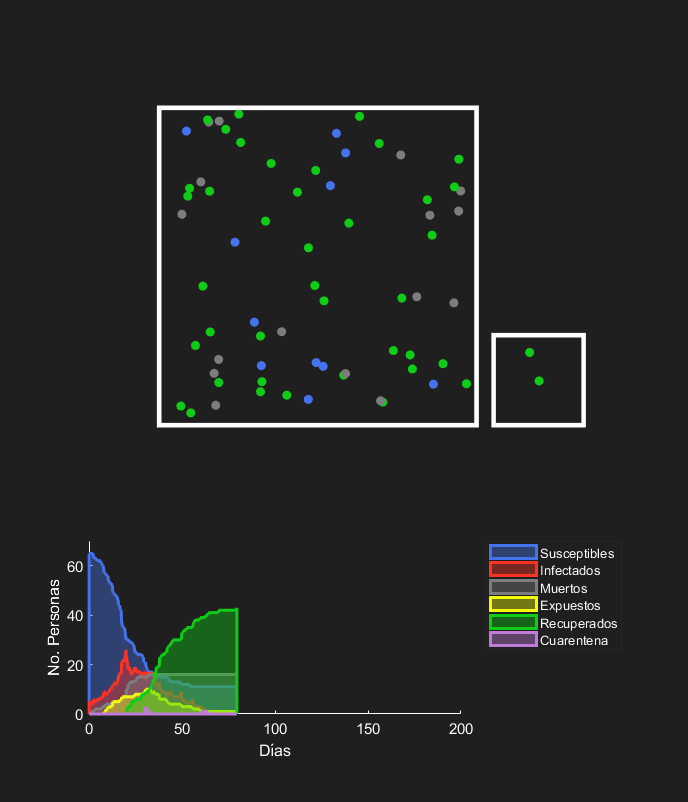

% PARÁMETROS SIMULACIÓN ============================================

clear;
DuracionSim = 200;                              % Duración en días para la simulación
dt = 0.1;                                       % Periodo de muestreo
MaxIter = DuracionSim / dt;                     % Número de iteraciones máximo que realizará el algoritmo
CrearVideo = 1;                                 % Crear video de la figura mostrada
PerformanceMode = 0;                            % Eliminar gráfica de "area" para evitar alentar el programa
%rng(0);                                        % Fijar una seed para hacer los resultados reproducibles

% PARÁMETROS FÍSICOS PARTÍCULAS =====================================
    
Poblacion = 70;                                 % Número de partículas
PorcentajeMovil = 0.75;                         % Porcentaje total de partículas en movimiento
ParticulasMoviles = randi([1 Poblacion], floor(Poblacion*PorcentajeMovil), 1);

% Posición de partículas
SizePartArea = 20;                              % Tamaño del "cuadro" principal (No recomendado cambiar)
PosMax = SizePartArea/2;                        % Posición máxima para las partículas de la caja principal
PosMin = -PosMax;                               % Posición mínima para las partículas de la caja principal
Pos = unifrnd(PosMin, PosMax, [Poblacion 2]);   % Posiciones aleatorias dentro de la caja principal
LimPosX = repmat([PosMin PosMax],Poblacion,1);  % Límites dentro de los que se pueden desplazar las partículas
LimPosY = repmat([PosMin PosMax],Poblacion,1);

% Velocidad inicial de partículas
MaxVel = 2;                                     % Velocidad máxima para partículas
Vel = zeros(Poblacion, 2);                      % Velocidad (X,Y) de partículas
Vel(ParticulasMoviles,:) = MaxVel * rand(numel(ParticulasMoviles),2);

% PARÁMETROS SEIRDQ ===================================================

% Expuestos (E)
Expuestos = [];
TiempoLatencia = zeros(size(Expuestos));        % Tiempo en el que los expuestos adquirieron su estado
ProbNoInfeccion = 0.3;                          % Probabilidad que un infectado convierta a un susceptible en "expuesto"
PeriodoLatencia = 25;                           % Duración (Días) que dura el periodo de "expuesto" 
ProbRecuperacionSinSintomas = 0.1;              % Probabilidad que un "expuesto" pase a ser un "recuperado" sin infectarse primero
ExpuestosHistory = zeros(DuracionSim/dt,1);
ExpuestosHistory(1) = numel(Expuestos);

% Infectados (I)
InfectadosInit = 5;                             % Número de infectados iniciales
ProbContagio = 0.7;                             % Probabilidad de infectarse al entrar en contacto con un "infectado"
RadioInfeccion = 0.5;                           % Radio dentro del que tiene que estar una partícula para contagiarse
Infectados = randi([1 Poblacion], InfectadosInit, 1);
TiempoInfeccion = zeros(size(Infectados));
InfectadosHistory = zeros(DuracionSim/dt,1);
InfectadosHistory(1) = numel(Infectados);

% Recuperados (R)
TiempoRecuperacion = 20;                        % Tiempo (Días) que le toma a un infectado recuperarse
ProbRecuperacion = 0.2;                         % Probabilidad de recuperarse una vez se tiene la capacidad de recuperarse
Recuperados = [];
RecuperadosHistory = zeros(DuracionSim/dt,1);
RecuperadosHistory(1) = numel(Recuperados);

% Susceptibles (S)
SusceptiblesHistory = zeros(DuracionSim/dt,1);
SusceptiblesHistory(1) = Poblacion - numel(Infectados) - numel(Recuperados);

% Muertes (D)
Muertos = [];
MuertosHistory = zeros(DuracionSim/dt,1);
MuertosHistory(1) = numel(Muertos); 
PorcentajeCondicionesPrevias = 0.15;                                            % Porcentaje de la población total con condiciones previas
Edades = randi([0 100], Poblacion, 1);                                          % Se le asigna una edad entre 0 a 100 a cada partícula
CondicionesPrevias = rand(size(Edades)) > (1 - PorcentajeCondicionesPrevias);   % Se asigna aleatoriamente "condiciones previas" a diferentes partículas
ProbMuerteCondicionesPrevias = 0.9;                                             % Probabilidad de morir si se tienen condiciones previas.

EdadMaxKid = 4;                                                                 % Edad máxima hasta la cual los niños se consideran altamente vulnerables a la enfermedad
EdadMinAdult = 50;                                                              % Edad mínima hasta la cual los adultos se comienzan a considerar como altamente vulnerables
EdadesVulnerables = (Edades < EdadMaxKid) | (Edades > EdadMinAdult);            % Se determina si las partículas están en una edad vulnerable
ProbMuerteEdadVulnerable = 0.85;

PorcentajeSalud = rand(size(Edades));                                           % Porcentaje de salud de la partícula: 0 = Nada sano. 1 = Excelente condición
PorcentajeMuerteEnfermedad = 0.5;
ProbMuerteEnfermedad = PorcentajeMuerteEnfermedad * ones(Poblacion,1);

% Se obtiene el promedio de
%   - Vulnerabilidad por estar en edades vulnerables
%   - Vulnerabilidad por padecer de condiciones previas
%   - Porcentaje de enfermedad = 1 - PorcentajeSalud
% A este valor se le considera el punteo de vulnerabilidad de la partícula.
VulnerabilidadEdad = ProbMuerteEdadVulnerable * EdadesVulnerables;
VulnerabilidadCondiciones = ProbMuerteCondicionesPrevias * CondicionesPrevias;
Vulnerabilidad = mean([(1-PorcentajeSalud) VulnerabilidadCondiciones VulnerabilidadEdad],2);
ProbMuerteIndividual = Vulnerabilidad .* (Vulnerabilidad > (1 - ProbMuerteEnfermedad));

PeriodoChequeoMuerte = 1;                                                       % Número de días que pasan antes de revisar cuales partículas van a morir

% Cuarentena (Q)
Cuarentena = [];
CuarentenaHistory = zeros(DuracionSim/dt,1);
CuarentenaHistory(1) = numel(Cuarentena); 
ProbCuarentena = 0.1;                                   % Probabilidad que una partícula infectada caiga en cuarentena
TiempoEsperaHabilitarCuarentena = 30;                   % Tiempo (Días) que debe transcurrir antes de comenzar a poner en cuarentena
TiempoUltimoChequeo = 0;                                % Tiempo desde el último para ver a quienes se mete a cuarentena
TiempoEntreChequeos = 10;                               % Cada cuantos días se mete a cuarentena a nuevas partículas.

% COLORES ======================================================

Azul = [0.27 0.45 0.93];
Rojo = [1 0.2 0.14];
Negro = [0.12 0.12 0.12];
Blanco = [0.72 0.72 0.72];
Gris = [0.490 0.490 0.490];
Amarillo = [243, 252, 5]/255;
Morado = [191, 123, 215]/255;
Verde = [0.058, 0.8, 0.086];
Colores = repmat(Azul,Poblacion,1);                                         % Se asigna un color azul para todas las partículas al inicio
Colores(Infectados,:) = repmat(Rojo,numel(Infectados),1);                   % Se asigna color rojo a todas las partículas infectadas

% FIGURA ======================================================

close all; figure(1); clf;
set(0,'defaultfigurecolor',Negro);
figure('visible','on');

% Se centra la figura en pantalla
FigureWidth = 600;                                                          % Ancho del plot en "pts"
FigureHeight = 700;                                                         % Alto del plot en "pts"
ScreenSize = get(0,'ScreenSize');                                           % Se obtiene el tamaño de la pantalla. ScreenSize(3) = Ancho / ScreenSize(4) = Alto
set(gcf, 'Position',  [ScreenSize(3)/2 - FigureWidth/2, ScreenSize(4)/2 - FigureHeight/2, FigureWidth, FigureHeight]);

% Posiciones mínimas y máximas para los bordes de la caja pequeña de
% cuarentena o QBox
PosMinQBoxX = 1.2*PosMax;
PosMaxQBoxX = 1.2*PosMax + 0.25*SizePartArea;
PosMaxQBoxY = PosMin + 0.25*SizePartArea;
PosMinQBoxY = PosMin;

% El radio de infección está en metros, pero debe ser reexpresado en puntos
% para ser utilizado en "scatter()"
ax = gca;                                                                   % Propiedades de "axis" o ejes actuales
old_units = get(ax, 'Units');                                               % Unidades de los ejes actuales
set(ax, 'Units', 'points');                                                 % Se cambian las unidades de los ejes a puntos
PosAxis = get(ax, 'Position');                                              % Se obtiene el [left bottom width height] de la caja que encierra a los ejes
set(ax, 'Units', old_units);                                                % Se regresa a las unidades originales de los ejes
DimsPlotPuntos = min(PosAxis(3:4));                                         % Se obtiene el valor mínimo entre el "width" y el "height" de los axes en "points"
FactorConversion = DimsPlotPuntos / SizePartArea;
AreaRadioInfec = pi*(RadioInfeccion * FactorConversion)^2;

% SUBPLOT 1: Animación partículas ------------

% Plots
subplot(3,1,[1 2]); hold on;
Particulas = scatter(Pos(:,1), Pos(:,2),[], Colores,'filled');
RadioInfec = scatter(Pos(Infectados,1), Pos(Infectados,2), AreaRadioInfec, Rojo,'MarkerEdgeAlpha',0.4);
Borde = rectangle('Position',[1.04*PosMin 1.04*PosMin 1.04*SizePartArea 1.04*SizePartArea],'EdgeColor','w','LineWidth',3);
QBox = rectangle('Position',[0.96*PosMinQBoxX 1.04*PosMinQBoxY 1.18*0.25*SizePartArea 1.18*0.25*SizePartArea],'EdgeColor','w','LineWidth',3);

% Propiedades plot
Margen = 1.2;
axis([Margen*PosMin Margen*PosMax Margen*PosMin Margen*PosMax]); 
set(gca,'XTick',[],'YTick',[]); axis manual; axis equal;
set(gca,'YColor',Negro,'XColor',Negro,'Color',Negro);
hold off;

% SUBPLOT 2: Resumen de Modelo ------------

% Plots
subplot(3,1,3); hold on;
if PerformanceMode == 0
    Suscep = area(0, SusceptiblesHistory(1), 'FaceColor', Azul, 'FaceAlpha',0.4,'LineWidth',2,'EdgeColor',Azul);
    Infec = area(0, InfectadosHistory(1),'FaceColor', Rojo,'FaceAlpha',0.4,'LineWidth',2,'EdgeColor',Rojo);
    Recup = area(0, RecuperadosHistory(1),'FaceColor', Verde,'FaceAlpha',0.4,'LineWidth',2,'EdgeColor',Verde);
    Muert = area(0, MuertosHistory(1),'FaceColor', Gris,'FaceAlpha',0.4,'LineWidth',2,'EdgeColor',Gris);
    Expues = area(0, ExpuestosHistory(1),'FaceColor', Amarillo,'FaceAlpha',0.4,'LineWidth',2,'EdgeColor',Amarillo);
    Cuaren = area(0, RecuperadosHistory(1),'FaceColor', Morado,'FaceAlpha',0.4,'LineWidth',2,'EdgeColor',Morado);
    legend("Susceptibles", "Infectados", "Recuperados", "Muertos", "Expuestos", "Cuarentena", 'TextColor','w','Color','none','Location','northeastoutside');
end

% Propiedades plot
set(gca,'YColor','w','XColor','w','Color',Negro);
xlabel("Días",'Color','w');
ylabel("No. Personas",'Color','w');
axis([0 DuracionSim 0 Poblacion]); 
hold off;
set(gca,'Color',Negro);
set(gcf, 'MenuBar', 'none');
set(gcf, 'ToolBar', 'none');

% SETTINGS VIDEO =================================================
if CrearVideo
    Frame = getframe(gcf);
    Video = VideoWriter('Output.mp4','MPEG-4');
    Video.FrameRate = 60;
    open(Video);
end

for i = 2:MaxIter
    
    % Actualización posiciones usando método de Newton
    Pos = Pos + Vel * dt;
    
    % INFECCIÓN ======================================================
    
    DistanciasParts = getDistsBetweenParticles(Pos);                                        % Distancias entre todas las partículas
    [PartMain, PartAux] = find(DistanciasParts < RadioInfeccion);                           % Partículas infectadas en distancia de infección
    PartsEnColision = [PartMain PartAux];
    
    % InfecPresentes = Máscara con 1's donde hay infectados en "PartsEnColision" 
    % IndInfect = En que índices de "Infectados" podemos encontrar los diferentes elementos de "PartsEnColision"
    [InfecPresentes,IndInfec] = ismember(PartsEnColision,Infectados); 
    
    % Se suman las columnas de InfecPresentes. 
    %   - Valor fila = 0: Colisión entre partículas sanas
    %   - Valor fila = 1: Colisión entre partícula sana e infectada.
    %   - Valor fila = 2: Colisión entre partículas infectadas
    % Se quieren colisiones entre una sana y una infectada, entonces se
    % filtran las filas con una suma igual a 1.
    ColisionesInfecciosas = PartsEnColision(sum(InfecPresentes,2)==1,:);                             
    
    % Si se detectan colisiones "infecciosas" (Si alguno de los valores de
    % "ColisionesInfecciosas" es distinto de 0).
    if ~isempty(ColisionesInfecciosas)
        
        Infecciosos = intersect(ColisionesInfecciosas,Infectados);                          % Se extraen los índices ~= 0 de IndInfec. Luego se meten a Infectados para obtener los infectados en colisión
        Vulnerables = setdiff(ColisionesInfecciosas,Infecciosos);                           % Se obtienen la parte de "ColisionesInfecciones" que no corresponde a los "Infecciosos". 
        Vulnerables = setdiff(Vulnerables,Recuperados);
        Vulnerables = setdiff(Vulnerables,Expuestos);
        Vulnerables = setdiff(Vulnerables,Muertos);
        ProbContagioIndividual = rand(numel(Vulnerables),1) > (1 - ProbContagio);

        if sum(ProbContagioIndividual > 0)
            
            NuevosContagios = Vulnerables(ProbContagioIndividual == 1);                         % Se extraen los "NuevosContagios"
            ProbLatenciaIndividual = rand(numel(NuevosContagios),1) > (1 - ProbNoInfeccion);    % Probabilidad que la persona se infecte pero no muestre síntomas
            
            NuevosExpuestos = NuevosContagios(ProbLatenciaIndividual == 1);                     % Se agregan a expuestos las personas en latencia o en espera a mostrar síntomas.
            Expuestos = [Expuestos ; NuevosExpuestos(:)];
            TiempoLatencia = [TiempoLatencia ; i*dt*ones(size(NuevosExpuestos(:)))];
            Colores(Expuestos,:) = repmat(Amarillo,numel(Expuestos),1);
            
            NuevosInfectados = Vulnerables(ProbLatenciaIndividual == 0);                        % Se agregan a infectados aquellos "Vulnerables" que pasen el chequeo de probabilidad.
            Infectados = [Infectados ; NuevosInfectados(:)];                                    % Se agrega a la lista de infectados a los nuevos infectados
            TiempoInfeccion = [TiempoInfeccion; i*dt*ones(size(NuevosInfectados(:)))];          % Se toma nota del tiempo en el que se infectaron los "NuevosInfectados"
            Colores(Infectados,:) = repmat(Rojo,numel(Infectados),1);                           % Se cambia el color de los infectados a rojo
        end
    end
   
    % EXPOSICIÓN ========================================================
    
    LatenciaTerminada = (i*dt - TiempoLatencia) > PeriodoLatencia;
    ExpuestosASiguienteEtapa = Expuestos(LatenciaTerminada == 1);
    Prob = rand(numel(ExpuestosASiguienteEtapa),1);

    ProbRecupSinSintomasIndividual = Prob > (1 - ProbRecuperacionSinSintomas);
    
    if ~isempty(ProbRecupSinSintomasIndividual) || all(ProbRecupSinSintomasIndividual)
        NuevosRecuperados = ExpuestosASiguienteEtapa(ProbRecupSinSintomasIndividual == 1);  % ID de partículas que pasaron el check de probabilidad (Van a recuperarse)    
        Recuperados = [Recuperados ; NuevosRecuperados(:)];                                 % Se agregan los nuevos recuperados
        Colores(Recuperados,:) = repmat(Verde,numel(Recuperados),1);
        
        NuevosInfectados = ExpuestosASiguienteEtapa(ProbRecupSinSintomasIndividual == 0);   % ID de partículas que no pasaron check de probabilidad (Van a convertirse en infectados)
        Infectados = [Infectados ; NuevosInfectados(:)];                                    % Se agregan los nuevos infectados
        Colores(Infectados,:) = repmat(Rojo,numel(Infectados),1); 
        
        [~,~,IndExpuestosAInfectar] = intersect(NuevosInfectados,Expuestos);                % Índices de los expuestos a infectar
        TiempoInfeccion = [TiempoInfeccion ; TiempoLatencia(IndExpuestosAInfectar)];        % Tiempo de infección inicial = Tiempo en el que por primera vez quedaron latentes.
        
        [~,~,IndExpuestosAEliminar] = intersect(ExpuestosASiguienteEtapa,Expuestos);  
        Expuestos(IndExpuestosAEliminar) = [];                                              % Se eliminan los expuestos que se agregaron a recuperados o infectados
        TiempoLatencia(IndExpuestosAEliminar) = [];                                         % Se eliminan también los tiempos de latencia de los puntos ahora recuperados o infectados
    end
    
    % MUERTE ===========================================================
    
    if mod(dt*i, PeriodoChequeoMuerte) == 0                                                 % Cada "PeriodoChequeoMuerte" se revisa cuales partículas morirán
        ProbMuerteActual = rand(size(Infectados));                                          % Se tira un dado para ver la probabilidad de muerte actual de la partícula
        InfectadosAMorir = (1-ProbMuerteIndividual(Infectados)) < ProbMuerteActual;         % Si el % actual es mayor a la probabilidad de muerte individual, la partícula va a morir
        
        if sum(InfectadosAMorir > 0)
            NuevosMuertos = Infectados(InfectadosAMorir == 1);
            Muertos = [Muertos ; NuevosMuertos(:)];
            Vel(Muertos,:) = 0;                                                             % Se elimina la velocidad de las partículas muertas
            
            [~,~,IndInfectadosAEliminar] = intersect(NuevosMuertos,Infectados);             % Índices de los infectados a eliminar de la lista de infectados
            [~,~,IndCuarentenaAEliminar] = intersect(Infectados(IndInfectadosAEliminar),Cuarentena);
            Cuarentena(IndCuarentenaAEliminar) = [];
            Infectados(IndInfectadosAEliminar) = [];                                        % Se eliminan los infectados que se agregaron a recuperados
            TiempoInfeccion(IndInfectadosAEliminar) = [];                                   % Se eliminan también los tiempos iniciales de infección de los infectados eliminados
            
            Colores(Muertos,:) = repmat(Gris,numel(Muertos),1);                             % Se pintan de morado las partículas muertas
        end
    end
    
    % RECUPERACIÓN =====================================================
    
    PuedeRecuperarse = (i*dt - TiempoInfeccion) > TiempoRecuperacion;                               % Si tiempo de infección actual de infectado > tiempo de recuperación se permite recuperarse
    InfectadosPorRecuperarse = Infectados(PuedeRecuperarse == 1);                                   % Se extrae el ID de las partículas que pueden recuperarse
    ProbRecuperacionIndividual = rand(numel(InfectadosPorRecuperarse),1) > (1 - ProbRecuperacion);  % Se calcula la probabilidad de recuperarse por partícula en "InfectadosPorRecuperarse"
    
    if sum(ProbRecuperacionIndividual > 0)
        NuevosRecuperados = InfectadosPorRecuperarse(ProbRecuperacionIndividual == 1);      % Se extrae el ID de las partículas que pasaron el check de probabilidad      
        Recuperados = [Recuperados ; NuevosRecuperados(:)];                                 % Se agregan recuperados a la lista
        
        [~,~,IndInfectadosAEliminar] = intersect(NuevosRecuperados,Infectados);             % Índices de los infectados a eliminar de la lista de infectados
        [~,~,IndCuarentenaAEliminar] = intersect(Infectados(IndInfectadosAEliminar),Cuarentena);
        Cuarentena(IndCuarentenaAEliminar) = [];
        Infectados(IndInfectadosAEliminar) = [];                                            % Se eliminan los infectados que se agregaron a recuperados
        TiempoInfeccion(IndInfectadosAEliminar) = [];                                       % Se eliminan también los tiempos iniciales de infección de los infectados eliminados
        
        Colores(Recuperados,:) = repmat(Verde,numel(Recuperados),1);
    end
    
    % CUARENTENA =====================================================
    
    PuedeCuarentenarse = (i*dt > TiempoEsperaHabilitarCuarentena) & (i*dt - TiempoUltimoChequeo > TiempoEntreChequeos);
    
    if sum(PuedeCuarentenarse > 0)
        TiempoUltimoChequeo = i*dt;
        ProbCuarentenaIndividual = rand(numel(Infectados),1) > (1 - ProbCuarentena);
        NuevosCuarentena = Infectados(ProbCuarentenaIndividual == 1);                               % Se agregan los infectados a "Cuarentena"
        NuevosCuarentena = setdiff(NuevosCuarentena,Cuarentena);                                    % No se toman en cuenta como "Nuevos" los elementos ya previamente en cuarentena
        Cuarentena = [Cuarentena; NuevosCuarentena(:)];                                             % No se eliminan de "infectados". Así estos pueden seguir muriendo o recuperándose

        % Nuevas posiciones aleatorias en QBox
        %Pos(NuevosCuarentena,1) = unifrnd(PosMinQBoxX, PosMaxQBoxX, [numel(NuevosCuarentena) 1]);  % Se re-posiciona la partícula en la caja adyacente de cuarentena
        %Pos(NuevosCuarentena,2) = unifrnd(PosMinQBoxY, PosMaxQBoxY, [numel(NuevosCuarentena) 1]);  % Se re-posiciona la partícula en la caja adyacente de cuarentena
        
        % Nuevas posiciones en el centro de QBox
        Pos(NuevosCuarentena,1) = PosMinQBoxX + ((PosMaxQBoxX - PosMinQBoxX) / 2);                  % Se re-posiciona la partícula en la caja adyacente de cuarentena
        Pos(NuevosCuarentena,2) = PosMinQBoxY + ((PosMaxQBoxY - PosMinQBoxY) / 2);                  % Se re-posiciona la partícula en la caja adyacente de cuarenten
        Vel(NuevosCuarentena,:) = Vel(NuevosCuarentena,:) * 0.75;                                   % Se reduce la velocidad de la partícula
        LimPosX(NuevosCuarentena,:) = repmat([PosMinQBoxX PosMaxQBoxX],numel(NuevosCuarentena),1);  % Se re-establecen los límites de la caja en los que están los nuevos cuarentenados
        LimPosY(NuevosCuarentena,:) = repmat([PosMinQBoxY PosMaxQBoxY],numel(NuevosCuarentena),1);
        
    end
    
    % COLISIÓN CON PAREDES ===========================================
    
    % Si se llega a los bordes del plot la velocidad de la partícula se
    % refleja dependiendo de si es un borde horizontal o vertical
    OutOfBoundsPartX = (Pos(:,1) < LimPosX(:,1)) | (Pos(:,1) > LimPosX(:,2));     % Choque bordes verticales
    Vel(OutOfBoundsPartX,1) = -Vel(OutOfBoundsPartX,1);
    OutOfBoundsPartY = (Pos(:,2) < LimPosY(:,1)) | (Pos(:,2) > LimPosY(:,2));     % Choque bordes horizontales
    Vel(OutOfBoundsPartY,2) = -Vel(OutOfBoundsPartY,2);
    
    % ACTUALIZACIÓN PLOT =============================================
    
    % Actualización partículas
    Particulas.XData = Pos(:,1);
    Particulas.YData = Pos(:,2);
    Particulas.CData = Colores;
    RadioInfec.XData = Pos(Infectados,1);
    RadioInfec.YData = Pos(Infectados,2);
    
    % Actualización de historial de cantidades SIR
    ExpuestosHistory(i) = numel(Expuestos);
    InfectadosHistory(i) = numel(Infectados) - numel(Cuarentena);
    RecuperadosHistory(i) = numel(Recuperados);
    MuertosHistory(i) = numel(Muertos);
    CuarentenaHistory(i) = numel(Cuarentena);
    SusceptiblesHistory(i) = Poblacion - numel(Infectados) - numel(Recuperados) - numel(Expuestos) - numel(Muertos);
    
    % Actualización gráfica cuenta
    if PerformanceMode == 0
        Infec.XData = (1:i)*dt;
        Infec.YData = InfectadosHistory(1:i);
        Recup.XData = (1:i)*dt;
        Recup.YData = RecuperadosHistory(1:i);
        Suscep.XData = (1:i)*dt;
        Suscep.YData = SusceptiblesHistory(1:i);
        Expues.XData = (1:i)*dt;
        Expues.YData = ExpuestosHistory(1:i);
        Muert.XData = (1:i)*dt;
        Muert.YData = MuertosHistory(1:i);
        Cuaren.XData = (1:i)*dt;
        Cuaren.YData = CuarentenaHistory(1:i);
    end
    
    drawnow
    
    % Escritura de frames a video
    if CrearVideo
        Frame = getframe(gcf);
        writeVideo(Video,Frame);
    end
    
    if numel(Infectados) + numel(Expuestos) == 0
        break
    end
    
end


if CrearVideo
   close(Video); 
end

% Inicialmente se cambia el color default de fondo de todas las figuras de
% Matlab a negro. Aquí se retorna a su valor normal.
set(0,'defaultfigurecolor',[240 240 240]/255);